clear all;


load idealECG.mat;
load nECG.mat;

fs = 128;
N = length(idealECG);
t = (0:N-1)/fs;

D_t = 1/fs;

% ECG modelling parameters

theta_i = [2*pi/3, 11*pi/12, pi, 13*pi/12, 3*pi/2];
% theta_i = [-1*pi/3, -1*pi/12, 0, pi/12, pi/2];
a_i = [1.2, -5, 30, -7.5, 0.75];
b_i = [0.25, 0.1, 0.1, 0.1, 0.4];

omega = 2*pi/0.8;

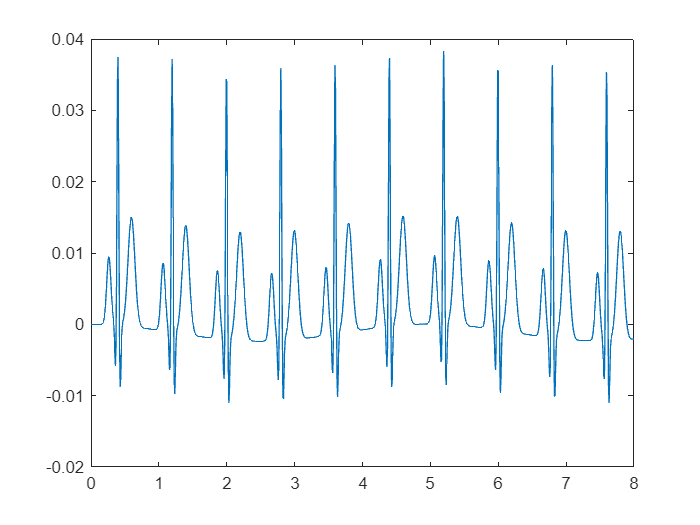

% Synthetic ECG signal
Theta = zeros(size(nECG));
z = zeros(size(nECG));

for n = (2:N)
    Theta(n) = mod(Theta(n-1) + omega*D_t,2*pi);
    z_dot = -1.5e-3*sin(2*pi*0.2*n/fs);
    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        z_dot = z_dot - a_i(i)*D_theta*exp(-0.5*D_theta^2/b_i(i)^2);
    end
    z(n) = z(n-1) + D_t*z_dot;
end

figure(1);
plot(t,z);
xlim([0,8]);
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Synthesized_ECG.png');

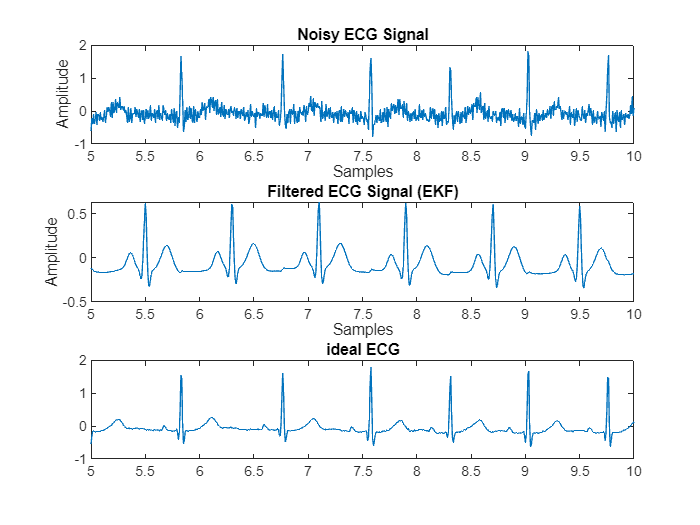

a_i = [1.2, -5, 30, -7.5, 0.75]*20;
% EKF

Theta = zeros(size(nECG));
z = zeros(size(nECG));

R = eye(2)*1e-6;
Q = 0.027;
sigma = eye(2)*1;

C = [0 1];

for n = (2:N)

%%%%%%%%% Prediction %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Theta(n) = mod(Theta(n-1) + omega*D_t,2*pi);
    z_dot = 0;
    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        z_dot = z_dot - a_i(i)*D_theta*exp(-0.5*D_theta^2/b_i(i)^2);
    end
    z(n) = z(n-1) + D_t*z_dot;
    s = [Theta(n), z(n)]';

%%%%%%%%% Jacobian of state transition %%%%%%%%%%%%%%%%%%%%%%% 
       
    G = eye(2);

    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        G(2,1) = G(2,1) - D_t * a_i(i)*(1 - D_theta^2 / b_i(i)^2) * exp(-0.5*D_theta^2 / b_i(i)^2);
    end

%%%%%%%%% Error covariance of prediction %%%%%%%%%%%%%%%%%%%%%
    sigma = G*sigma*G' + R;

%%%%%%%%% Kalman Gain %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    K = sigma*C'/(C*sigma*C' + Q);

%%%%%%%%% Correction using input signal %%%%%%%%%%%%%%%%%%%%%%
    s = s + K*(nECG(n) -C*s);
    Theta(n) = s(1);
    z(n) = s(2);
    sigma = (eye(2) - K*C)*sigma;
end

% MSE = mean((z-idealECG).^2)
figure(2);
subplot(3, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(3, 1, 2);
plot(t,z);
title('Filtered ECG Signal (EKF)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);

subplot(3,1,3);
plot(t,idealECG);
xlim([5,10]);
title('ideal ECG');
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_basic_EKF(R=1e-6).png');

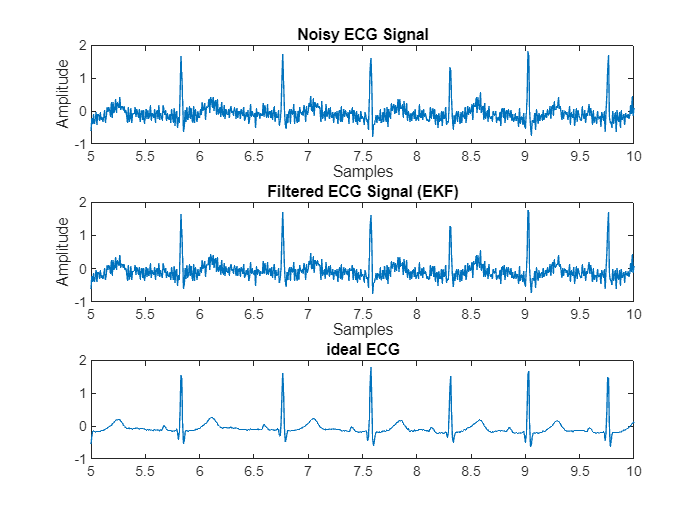

% EKF

Theta = zeros(size(nECG));
z = zeros(size(nECG));

R = eye(2)*1;
Q = 0.027;
sigma = eye(2)*1;

C = [0 1];

for n = (2:N)

%%%%%%%%% Prediction %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Theta(n) = mod(Theta(n-1) + omega*D_t,2*pi);
    z_dot = 0;
    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        z_dot = z_dot - a_i(i)*D_theta*exp(-0.5*D_theta^2/b_i(i)^2);
    end
    z(n) = z(n-1) + D_t*z_dot;
    s = [Theta(n), z(n)]';

%%%%%%%%% Jacobian of state transition %%%%%%%%%%%%%%%%%%%%%%% 
       
    G = eye(2);

    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        G(2,1) = G(2,1) - D_t * a_i(i)*(1 - D_theta^2 / b_i(i)^2) * exp(-0.5*D_theta^2 / b_i(i)^2);
    end

%%%%%%%%% Error covariance of prediction %%%%%%%%%%%%%%%%%%%%%
    sigma = G*sigma*G' + R;

%%%%%%%%% Kalman Gain %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    K = sigma*C'/(C*sigma*C' + Q);

%%%%%%%%% Correction using input signal %%%%%%%%%%%%%%%%%%%%%%
    s = s + K*(nECG(n) -C*s);
    Theta(n) = s(1);
    z(n) = s(2);
    sigma = (eye(2) - K*C)*sigma;
end

% MSE = mean((z-idealECG).^2)
figure(2);
subplot(3, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(3, 1, 2);
plot(t,z);
title('Filtered ECG Signal (EKF)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);

subplot(3,1,3);
plot(t,idealECG);
xlim([5,10]);
title('ideal ECG');
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_basic_EKF(R=1).png');

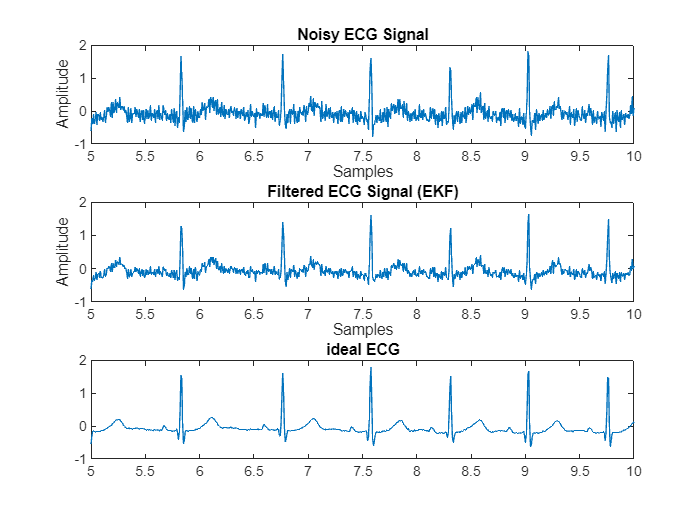

A =      1     2     3     4     5     6


M = 3.5000

% EKF

Theta = zeros(size(nECG));
z = zeros(size(nECG));

R = eye(2)*1e-6;
Q = 0.027;
sigma = eye(2)*1;
MSE = 1;

C = [0 1];

for j = linspace(0.01,0.07,60)
    for k = linspace(0.01,0.07,60)
        R = [k, 0; 0, j];

        for n = (2:N)
        
        %%%%%%%%% Prediction %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            Theta(n) = mod(Theta(n-1) + omega*D_t,2*pi);
            z_dot = 0;
            for i = (1:5)
                D_theta = Theta(n)-theta_i(i);
                z_dot = z_dot - a_i(i)*D_theta*exp(-0.5*D_theta^2/b_i(i)^2);
            end
            z(n) = z(n-1) + D_t*z_dot;
            s = [Theta(n), z(n)]';
        
        %%%%%%%%% Jacobian of state transition %%%%%%%%%%%%%%%%%%%%%%% 
               
            G = eye(2);
        
            for i = (1:5)
                D_theta = Theta(n)-theta_i(i);
                G(2,1) = G(2,1) - D_t * a_i(i)*(1 - D_theta^2 / b_i(i)^2) * exp(-0.5*D_theta^2 / b_i(i)^2);
            end
        
        %%%%%%%%% Error covariance of prediction %%%%%%%%%%%%%%%%%%%%%
            sigma = G*sigma*G' + R;
        
        %%%%%%%%% Kalman Gain %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            K = sigma*C'/(C*sigma*C' + Q);
        
        %%%%%%%%% Correction using input signal %%%%%%%%%%%%%%%%%%%%%%
            s = s + K*(nECG(n) -C*s);
            Theta(n) = s(1);
            z(n) = s(2);
            sigma = (eye(2) - K*C)*sigma;
        end
        MSE_jk = mean((z-idealECG).^2);

        if (MSE> MSE_jk)
            MSE = MSE_jk;
            k_m = k;
            j_m = j;
            z_m = z;
        end
    end
end

% MSE = mean((z-idealECG).^2)
figure(2);
subplot(3, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(3, 1, 2);
plot(t,z_m);
title('Filtered ECG Signal (EKF)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);

subplot(3,1,3);
plot(t,idealECG);
xlim([5,10]);
title('ideal ECG');
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_basic_EKF(R_opt).png');